# Lab 5 Robótica

### Allan Serrato, Juan Fernando Ramirez

%Para inicializar el rcv toolbox:
startup_rvc;

Robotics, Vision & Control: (c) Peter Corke 1992-2011 http://www.petercorke.com
- Robotics Toolbox for Matlab (release 9.10)
 - pHRIWARE (release 1.1): pHRIWARE is Copyrighted by Bryan Moutrie (2013-2022) (c)
Run rtbdemo to explore the toolbox
- Machine Vision Toolbox for Matlab (release 3.4)


## Módelo Cinemático Pincher PhantomX (Nuevo):

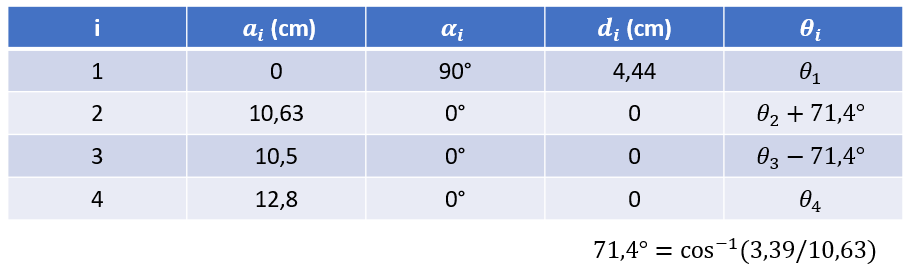

clear;
syms theta1 theta2 theta3 theta4
alpha2=acos(3.39/10.63) %radians

alpha2 = 1.2462

alpha2d=alpha2*180/pi %degrees

alpha2d = 71.4031

%MTH(ai,alphai,di,thetai,angleType0=rad)
% MTH de O1 respecto a O0
MTH01 = MTHDH(0,90,4.44,theta1,2) %degree and rad 

$$MTH01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & \frac{111}{25}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% MTH de O2 respecto a O1
MTH12 = MTHDH(10.63,0,0,theta2+alpha2,2)  %degree and rad 

$$MTH12 = \left(\begin{array}{cccc} \cos\left(\theta_{2}+\frac{2806234433688379}{2251799813685248}\right) & -\sin\left(\theta_{2}+\frac{2806234433688379}{2251799813685248}\right) & 0 & \frac{1063\,\cos\left(\theta_{2}+\frac{2806234433688379}{2251799813685248}\right)}{100}\\ \sin\left(\theta_{2}+\frac{2806234433688379}{2251799813685248}\right) & \cos\left(\theta_{2}+\frac{2806234433688379}{2251799813685248}\right) & 0 & \frac{1063\,\sin\left(\theta_{2}+\frac{2806234433688379}{2251799813685248}\right)}{100}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% MTH de O3 respecto a O2
MTH23 = MTHDH(10.5,0,0,theta3-alpha2,2)%degrees and rad

$$MTH23 = \left(\begin{array}{cccc} \cos\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right) & -\sin\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right) & 0 & \frac{21\,\cos\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right)}{2}\\ \sin\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right) & \cos\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right) & 0 & \frac{21\,\sin\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right)}{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% MTH de O4 respecto a O3
MTH34 = MTHDH(12.8,0,0,theta4,2) %degree and rad

$$MTH34 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right) & 0 & \frac{64\,\cos\left(\theta_{4}\right)}{5}\\ \sin\left(\theta_{4}\right) & \cos\left(\theta_{4}\right) & 0 & \frac{64\,\sin\left(\theta_{4}\right)}{5}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

 Modelo geométrico directo (cinemática directa).

%MTH de O5 respecto a O0.
MTH04=MTH01*MTH12*MTH23*MTH34

Gráfica del modelo con el Toolbox de PeterCorke:

%MATRIZ DH 
% columnas en orden: thetai, di, ai, alphai
%cada fila es un qi.
q1=[0 4.44 0 pi/2];
q2=[alpha2 0 10.63 0];
q3=[-alpha2 0 10.5 0];
q4=[0 0 12.8 0];
DH1 = [q1;q2;q3;q4]

DH1 =          0    4.4400         0    1.5708
    1.2462         0   10.6300         0
   -1.2462         0   10.5000         0
         0         0   12.8000         0


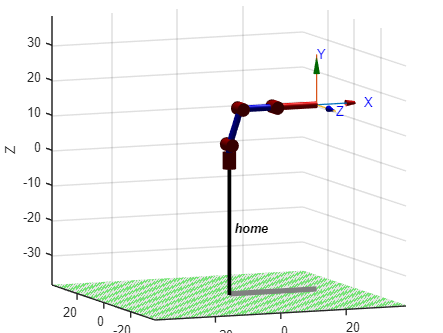

robot1 = SerialLink(DH1);

%plotear configuracion qz=[0,0,0,0]
robot1.name = 'home';
figure()
title('Home Peter Corke')
%toca agregar manualmente los offset de theta2 y theta3.
robot1.plot([0,alpha2,-alpha2,0])
view([-22.3 7.9])

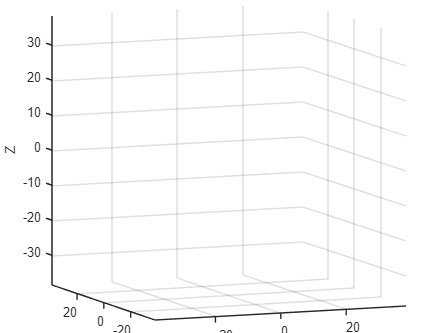

cla;

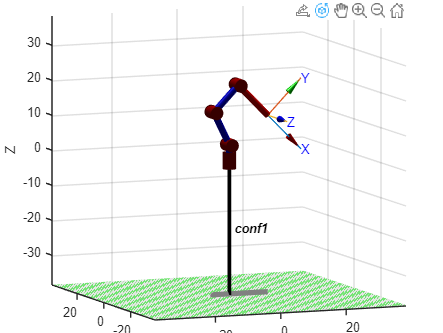

%configuracion q1=[0,45,0,-90]
robot1.name = 'conf1';
figure()
title('conf1 Peter Corke')
robot1.plot([0,pi/4+alpha2,-alpha2,-pi/2])
view([-22.3 7.9])

## Cinemática Inversa por MTHs Inversas.

Lo primero es saber que pose va a tener el robot: 

MTH04 con coordenadas dadas: (Px.Py,Pz).

Definir Limites para theta4 para que el marcador siempre quede recto.

Crear un Offset con el largo del Marcador,

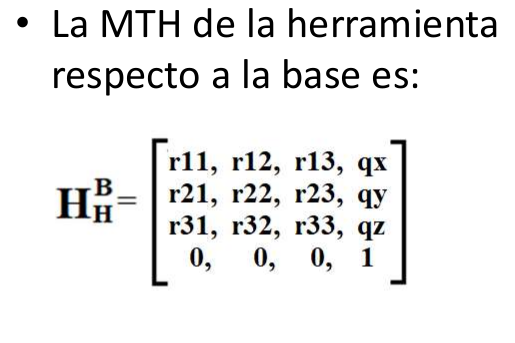

%Coordenadas deseadas en cm: 
P=[10, 10, 10];
%Matriz de transferencia nueva:
syms theta1 theta2 theta3 theta4 x1 x2 x3 y1 y2 y3 z1 z2 z3
MTHBH=[x1 x2 x3 P(1); y1 y2 y3 P(2); z1 z2 z3 P(3);0 0 0 1]

$$MTHBH = \left(\begin{array}{cccc} x_{1} & x_{2} & x_{3} & 10\\ y_{1} & y_{2} & y_{3} & 10\\ z_{1} & z_{2} & z_{3} & 10\\ 0 & 0 & 0 & 1 \end{array}\right)$$

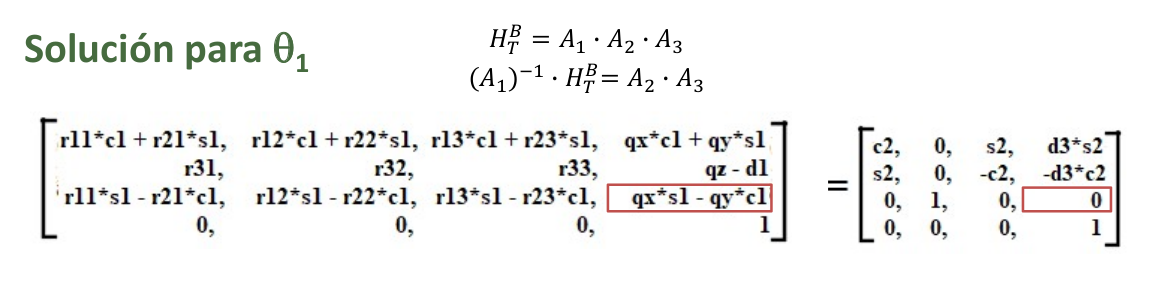

- **Solución para theta1: **

Am1=MTHinv(MTH01);
eq1iz=Am1*MTHBH;
eq1dr=MTH12*MTH23*MTH34;
eq1= eq1iz==eq1dr;
eq1=eq1(1:3,4)

$$eq1 = \begin{array}{l} \left(\begin{array}{c} \sigma_{2}+\sigma_{1}=\frac{1063\,\sigma_{6}}{100}+\frac{21\,\sigma_{6}\,\sigma_{8}}{2}-\frac{21\,\sigma_{5}\,\sigma_{7}}{2}+\frac{64\,\cos\left(\theta_{4}\right)\,\sigma_{3}}{5}-\frac{64\,\sin\left(\theta_{4}\right)\,\sigma_{4}}{5}\\ \frac{139}{25}=\frac{1063\,\sigma_{5}}{100}+\frac{21\,\sigma_{6}\,\sigma_{7}}{2}+\frac{21\,\sigma_{8}\,\sigma_{5}}{2}+\frac{64\,\cos\left(\theta_{4}\right)\,\sigma_{4}}{5}+\frac{64\,\sin\left(\theta_{4}\right)\,\sigma_{3}}{5}\\ \sigma_{1}-\sigma_{2}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=10\,\sin\left(\bar{\theta_{1}}\right)\\ \sigma_{2}=10\,\cos\left(\bar{\theta_{1}}\right)\\ \sigma_{3}=\sigma_{6}\,\sigma_{8}-\sigma_{5}\,\sigma_{7}\\ \sigma_{4}=\sigma_{6}\,\sigma_{7}+\sigma_{8}\,\sigma_{5}\\ \sigma_{5}=\sin\left(\theta_{2}+\frac{2806234433688379}{2251799813685248}\right)\\ \sigma_{6}=\cos\left(\theta_{2}+\frac{2806234433688379}{2251799813685248}\right)\\ \sigma_{7}=\sin\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right)\\ \sigma_{8}=\cos\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right) \end{array}$$

eqtheta1=eq1(3)

$$eqtheta1 = 10\,\sin\left(\bar{\theta_{1}}\right)-10\,\cos\left(\bar{\theta_{1}}\right)=0$$

q1=solve(eqtheta1) %rad

$$q1 = \frac{\pi }{4}$$

Implementación de algoritmo de iteración para estos.

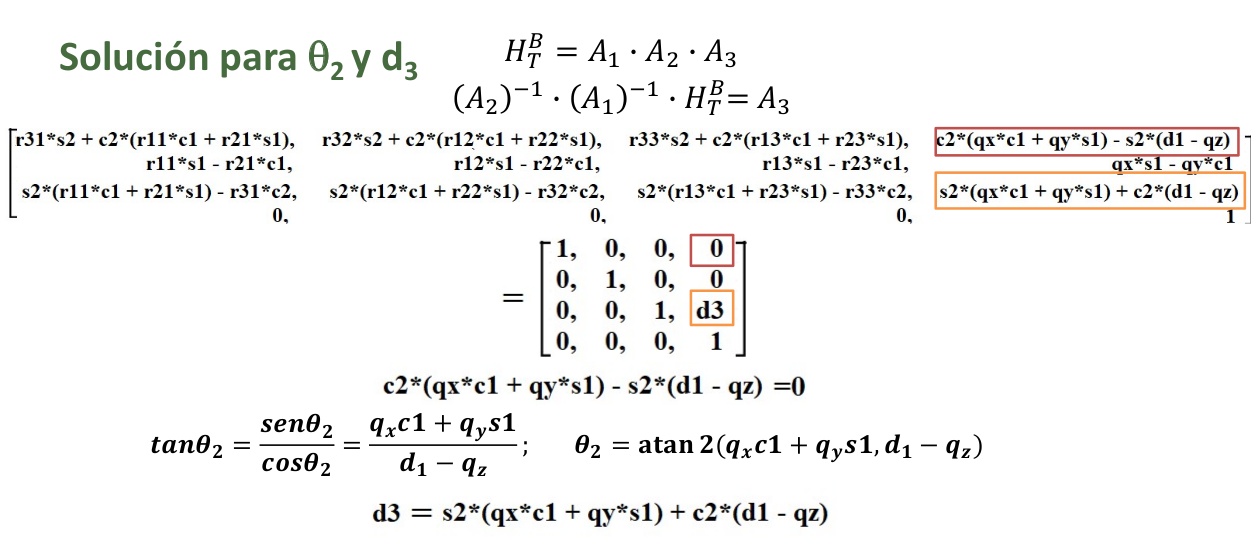

- **Solución para theta2 (12 posibles soluciones):**

%Igualdad multiplicada por A2^-1:
A2m1=MTHinv(MTH12);
eq2iz=A2m1*Am1*MTHBH;
eq2dr=MTH23*MTH34;
eq2= eq2iz==eq2dr;
eq2= eq2(1:3,4)

$$eq2 = \begin{array}{l} \left(\begin{array}{c} \frac{139\,\sin\left(\sigma_{5}\right)}{25}-\frac{1063\,\sin\left(\sigma_{5}\right)\,\sigma_{3}}{100}+10\,\cos\left(\bar{\theta_{1}}\right)\,\cos\left(\sigma_{5}\right)+10\,\sin\left(\bar{\theta_{1}}\right)\,\cos\left(\sigma_{5}\right)-\frac{1063\,\sigma_{4}\,\cos\left(\sigma_{5}\right)}{100}=\frac{21\,\sigma_{2}}{2}+\frac{64\,\sigma_{2}\,\cos\left(\theta_{4}\right)}{5}-\frac{64\,\sigma_{1}\,\sin\left(\theta_{4}\right)}{5}\\ \frac{139\,\cos\left(\sigma_{5}\right)}{25}-10\,\sin\left(\sigma_{5}\right)\,\cos\left(\bar{\theta_{1}}\right)-10\,\sin\left(\sigma_{5}\right)\,\sin\left(\bar{\theta_{1}}\right)+\frac{1063\,\sin\left(\sigma_{5}\right)\,\sigma_{4}}{100}-\frac{1063\,\sigma_{3}\,\cos\left(\sigma_{5}\right)}{100}=\frac{21\,\sigma_{1}}{2}+\frac{64\,\sigma_{2}\,\sin\left(\theta_{4}\right)}{5}+\frac{64\,\sigma_{1}\,\cos\left(\theta_{4}\right)}{5}\\ 10\,\sin\left(\bar{\theta_{1}}\right)-10\,\cos\left(\bar{\theta_{1}}\right)=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right)\\ \sigma_{2}=\cos\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right)\\ \sigma_{3}=\sin\left(\theta_{2}+\frac{2806234433688379}{2251799813685248}\right)\\ \sigma_{4}=\cos\left(\theta_{2}+\frac{2806234433688379}{2251799813685248}\right)\\ \sigma_{5}=\bar{\theta_{2}}+\frac{2806234433688379}{2251799813685248} \end{array}$$


%Crear Sistema de ecuaciones con las ecuaciones de theta1:
eq1p=subs(eq1,theta1,q1);
eq2p=subs(eq2,theta1,q1);
eq32=[eq1p(1:2); eq2p(1:2)]

$$eq32 = \begin{array}{l} \left(\begin{array}{c} 10\,\sqrt{2}=\frac{1063\,\sigma_{7}}{100}+\frac{21\,\sigma_{7}\,\sigma_{6}}{2}-\frac{21\,\sigma_{5}\,\sigma_{4}}{2}+\frac{64\,\cos\left(\theta_{4}\right)\,\sigma_{2}}{5}-\frac{64\,\sin\left(\theta_{4}\right)\,\sigma_{3}}{5}\\ \frac{139}{25}=\frac{1063\,\sigma_{5}}{100}+\frac{21\,\sigma_{7}\,\sigma_{4}}{2}+\frac{21\,\sigma_{6}\,\sigma_{5}}{2}+\frac{64\,\cos\left(\theta_{4}\right)\,\sigma_{3}}{5}+\frac{64\,\sin\left(\theta_{4}\right)\,\sigma_{2}}{5}\\ \frac{139\,\sin\left(\sigma_{1}\right)}{25}-\frac{1063\,\sin\left(\sigma_{1}\right)\,\sigma_{5}}{100}+10\,\sqrt{2}\,\cos\left(\sigma_{1}\right)-\frac{1063\,\sigma_{7}\,\cos\left(\sigma_{1}\right)}{100}=\frac{21\,\sigma_{6}}{2}+\frac{64\,\sigma_{6}\,\cos\left(\theta_{4}\right)}{5}-\frac{64\,\sigma_{4}\,\sin\left(\theta_{4}\right)}{5}\\ \frac{139\,\cos\left(\sigma_{1}\right)}{25}-10\,\sqrt{2}\,\sin\left(\sigma_{1}\right)+\frac{1063\,\sin\left(\sigma_{1}\right)\,\sigma_{7}}{100}-\frac{1063\,\sigma_{5}\,\cos\left(\sigma_{1}\right)}{100}=\frac{21\,\sigma_{4}}{2}+\frac{64\,\sigma_{6}\,\sin\left(\theta_{4}\right)}{5}+\frac{64\,\sigma_{4}\,\cos\left(\theta_{4}\right)}{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\bar{\theta_{2}}+\frac{2806234433688379}{2251799813685248}\\ \sigma_{2}=\sigma_{7}\,\sigma_{6}-\sigma_{5}\,\sigma_{4}\\ \sigma_{3}=\sigma_{7}\,\sigma_{4}+\sigma_{6}\,\sigma_{5}\\ \sigma_{4}=\sin\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right)\\ \sigma_{5}=\sin\left(\theta_{2}+\frac{2806234433688379}{2251799813685248}\right)\\ \sigma_{6}=\cos\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right)\\ \sigma_{7}=\cos\left(\theta_{2}+\frac{2806234433688379}{2251799813685248}\right) \end{array}$$


%Soluciones a los diferentes sistemas: (en radianes)
[q2 q3p q4p]= solve(eq32(1:3)) %eq 1-3 sin 4

$$q2 = 1.0028519050630850003396735175262$$

$$q3p = 5.6499136939678822179955632824453$$

$$q4p = -19.752684711457449409880151673263$$


[q21 q31 q41]=solve(eq32(2:4)) %eq 2-4 sin 1

$$q21 = -226.94495142003040084517833685314$$

$$q31 = 99.509962170507870309085612842023$$

$$q41 = 59.322921190528141225077872830616$$


eq32p=[eq32(1); eq32(3:4)];
[q22 q32 q42]=solve(eq32p) %eq 1,3,4 sin 2

$$q22 = -226.94495142003040084517833469921$$

$$q32 = 99.5099621705078703090856077397$$

$$q42 = 59.322921190528141225077871958033$$


eq32p=[eq32(1:2); eq32(4)];
[q23 q33 q43]=solve(eq32p) %eq 1,2,4 sin 3

$$q23 = -226.94495142003040084517833469198$$

$$q33 = 99.509962170507870309085607722578$$

$$q43 = 59.322921190528141225077871955105$$

Hay 2 Sistemas Linealmente idenpendientes dentro del Sistema de ecuciones con las ecuaciones de A1 y A2.

(Pobrar ambas en el siguiente sistema de ecuaciones).

Sol1=double([q2 q3p q4p]) %Tienen mas sentido geométrico.

Sol1 =     1.0029    5.6499  -19.7527



Sol2=double([q21 q31 q41]) %Deben ser despues de cruzar 2pi.

Sol2 =  -226.9450   99.5100   59.3229


- **Solución para theta 3 y theta 4:**

%Igualdad multiplicada por A3^-1:
A3m1=MTHinv(MTH23);
eq3iz=A3m1*A2m1*Am1*MTHBH;
eq3dr=MTH34;
eq3= eq3iz==eq3dr;
eq3= eq3(1:3,4)


%Solución Reemplazando primer q2:
eq3p=subs(eq3,[theta1 theta2],[q1 Sol1(1)]);
eq3p=eq3p(1:2)

$$eq3p = \begin{array}{l} \left(\begin{array}{c} \frac{139\,\sin\left(\sigma_{4}\right)\,\cos\left(\frac{2532228083331665}{1125899906842624}\right)}{25}-\frac{21\,\sin\left(\sigma_{4}\right)\,\sigma_{2}}{2}+\frac{139\,\sin\left(\frac{2532228083331665}{1125899906842624}\right)\,\cos\left(\sigma_{4}\right)}{25}+10\,\sqrt{2}\,\left(\cos\left(\frac{2532228083331665}{1125899906842624}\right)\,\cos\left(\sigma_{4}\right)-\sin\left(\sigma_{4}\right)\,\sin\left(\frac{2532228083331665}{1125899906842624}\right)\right)-\cos\left(\sigma_{4}\right)\,\sigma_{1}-\frac{21\,\sigma_{3}\,\cos\left(\sigma_{4}\right)}{2}=\frac{64\,\cos\left(\theta_{4}\right)}{5}\\ \frac{139\,\cos\left(\frac{2532228083331665}{1125899906842624}\right)\,\cos\left(\sigma_{4}\right)}{25}-\frac{139\,\sin\left(\sigma_{4}\right)\,\sin\left(\frac{2532228083331665}{1125899906842624}\right)}{25}-10\,\sqrt{2}\,\left(\sin\left(\sigma_{4}\right)\,\cos\left(\frac{2532228083331665}{1125899906842624}\right)+\sin\left(\frac{2532228083331665}{1125899906842624}\right)\,\cos\left(\sigma_{4}\right)\right)+\sin\left(\sigma_{4}\right)\,\sigma_{1}+\frac{21\,\sin\left(\sigma_{4}\right)\,\sigma_{3}}{2}-\frac{21\,\sigma_{2}\,\cos\left(\sigma_{4}\right)}{2}=\frac{64\,\sin\left(\theta_{4}\right)}{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1063\,{\cos\left(\frac{2532228083331665}{1125899906842624}\right)}^{2}}{100}+\frac{1063\,{\sin\left(\frac{2532228083331665}{1125899906842624}\right)}^{2}}{100}\\ \sigma_{2}=\sin\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right)\\ \sigma_{3}=\cos\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right)\\ \sigma_{4}=\bar{\theta_{3}}-\frac{2806234433688379}{2251799813685248} \end{array}$$

[q3 q4]=solve(eq3p)

$$q3 = -0.63327161321170437558098719240904$$

$$q4 = -0.9031287899186898618451397178142$$


%Solución Reemplazando segundo q2:
eq3p=subs(eq3,[theta1 theta2],[q1 Sol2(1)]);
eq3p=eq3p(1:2)

$$eq3p = \begin{array}{l} \left(\begin{array}{c} \frac{139\,\sin\left(\sigma_{4}\right)\,\cos\left(\frac{508228364890743749}{2251799813685248}\right)}{25}-\frac{21\,\sin\left(\sigma_{4}\right)\,\sigma_{2}}{2}-\frac{139\,\sin\left(\frac{508228364890743749}{2251799813685248}\right)\,\cos\left(\sigma_{4}\right)}{25}+10\,\sqrt{2}\,\left(\cos\left(\frac{508228364890743749}{2251799813685248}\right)\,\cos\left(\sigma_{4}\right)+\sin\left(\sigma_{4}\right)\,\sin\left(\frac{508228364890743749}{2251799813685248}\right)\right)-\cos\left(\sigma_{4}\right)\,\sigma_{1}-\frac{21\,\sigma_{3}\,\cos\left(\sigma_{4}\right)}{2}=\frac{64\,\cos\left(\theta_{4}\right)}{5}\\ \frac{139\,\cos\left(\frac{508228364890743749}{2251799813685248}\right)\,\cos\left(\sigma_{4}\right)}{25}+\frac{139\,\sin\left(\sigma_{4}\right)\,\sin\left(\frac{508228364890743749}{2251799813685248}\right)}{25}-10\,\sqrt{2}\,\left(\sin\left(\sigma_{4}\right)\,\cos\left(\frac{508228364890743749}{2251799813685248}\right)-\sin\left(\frac{508228364890743749}{2251799813685248}\right)\,\cos\left(\sigma_{4}\right)\right)+\sin\left(\sigma_{4}\right)\,\sigma_{1}+\frac{21\,\sin\left(\sigma_{4}\right)\,\sigma_{3}}{2}-\frac{21\,\sigma_{2}\,\cos\left(\sigma_{4}\right)}{2}=\frac{64\,\sin\left(\theta_{4}\right)}{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1063\,{\cos\left(\frac{508228364890743749}{2251799813685248}\right)}^{2}}{100}+\frac{1063\,{\sin\left(\frac{508228364890743749}{2251799813685248}\right)}^{2}}{100}\\ \sigma_{2}=\sin\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right)\\ \sigma_{3}=\cos\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right)\\ \sigma_{4}=\bar{\theta_{3}}-\frac{2806234433688379}{2251799813685248} \end{array}$$

[q31 q41]=solve(eq3p)

$$q31 = 15.296505347240306887958937353988$$

$$q41 = 3.508931881267721232055243961224$$

Entonces tenemos dos grupos de soluciones: 

Sol1=double([q1 q2 q3 q4]) %radianes.

Sol1 =     0.7854    1.0029   -0.6333   -0.9031


Sol1d=Sol1.*(180/pi) %grados.

Sol1d =    45.0000   57.4592  -36.2838  -51.7455



Sol2=double([q1 q21 q31 q41]) %radianes.

Sol2 =     0.7854 -226.9450   15.2965    3.5089


Sol2d= Sol2.*(180/pi) %grados.

Sol2d = 1.0e+04 *

    0.0045   -1.3003    0.0876    0.0201


La Solucion 2 no tiene sentido geometrico (-13.003° como que no para q2).

**Comprobación de la solución obtenida:**

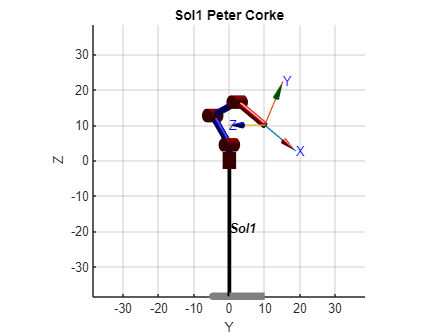

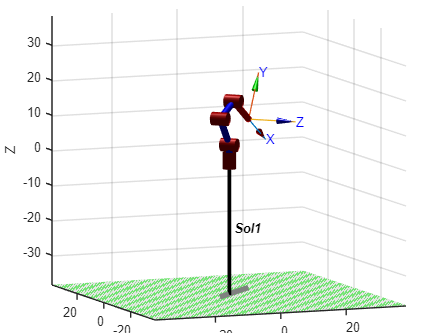

%configuracion Sol1=q1 q2 q3 q4 
robot1.name = 'Sol1';
figure()
title('Sol1 Peter Corke')
Sol1p=[Sol1(1),Sol1(2)+alpha2,Sol1(3)-alpha2,Sol1(4)];
robot1.plot(Sol1p)

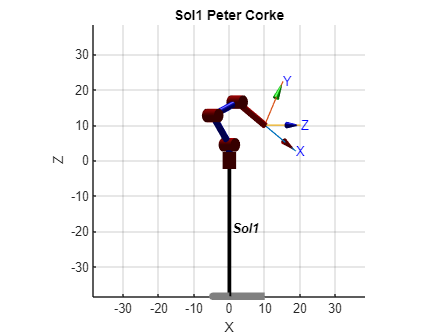

view([-22.3 7.9])
view([90 0])
view([0 0])

## Método Geométrico: 

Tengamos en cuenta que para el método geométrico los offsets iniciales de cada articulación se desprecian, y se sumarán a las soluciones aposteriori.

**Parámteros de entrada: **

x1 = 10 %cm

x1 = 10

y1 = 10 %cm

y1 = 10

z1 = 10 %cm

z1 = 10

phi = 0  %rad

phi = 0

Pose=[x1 y1 z1 phi];

- **Primer ángulo:**

Por geometría el primer ángulo será: 

(Poner Imagen)

q1=atan2(y1,x1) %rad

q1 = 0.7854

- **Desacomplamiento de muñeca para q4: **

Para poder resolver los otros tres ángulos, se considera el resto del brazo como un problema 2D de 3 ángulos. Por lo que se usa el método de desacoplamiento de muñeca, tomando la articulación q4 como la muñeca del sistema.

(Poner Imagen Desacoplamiento).

- **Posición de la muñeca (q4):**

Teniendo la matriz de transferencia del TCP respecto a la base. y la posición deseada se puede definir la posición de la muñeca como: 


$$P_{\mathrm{q4}}^0 =H_{\mathrm{TCP}}^0 \cdot P_{\mathrm{q4}}^{\mathrm{TCP}}$$


Donde por la orientación dada para el marco del TCP, la posición de la muñeca respecto al marco del TCP $P_{\mathrm{q4}}^{\mathrm{TCP}}$ sera: 


$$P_{\mathrm{q4}}^{\mathrm{TCP}} =\left\lbrack \begin{array}{c}
-a_4 \\
0\\
0
\end{array}\right\rbrack \;$$


%Posición de muñeca respecto a marco TCP:
PTCP4=[-12.8 0 0 1]'

PTCP4 =   -12.8000
         0
         0
    1.0000


Entonces, lo unico que nos falta por definir es la matriz de transferencia homogénea del TCP repecto a la base, la cual se definirá como: 


$$H_{\mathrm{TCP}}^0 =\left\lbrack \begin{array}{cc}
R_x \left(90\degree \right)\cdot R_z \left(\phi \;\right) & \left\lbrack \begin{array}{c}
x_1 \\
y_1 \\
z_1 
\end{array}\right\rbrack \\
0 & 1
\end{array}\right\rbrack$$


Rx90=[1 0 0; 0 cos(pi/2) -sin(pi/2); 0 sin(pi/2) cos(pi/2)];
Rzphi=[cos(phi) -sin(phi) 0; sin(phi) cos(phi) 0; 0 0 1];
%Matriz de transferencia de TCP respecto a 0:
H0TCP=[Rx90*Rzphi Pose(1:3)'; 0 0 0 1]

H0TCP =     1.0000         0         0   10.0000
         0    0.0000   -1.0000   10.0000
         0    1.0000    0.0000   10.0000
         0         0         0    1.0000


Posición de la muñeca: 

P04=H0TCP*PTCP4 %cm

P04 =    -2.8000
   10.0000
   10.0000
    1.0000


- **Solución problema 2R para q2 y q3: **

Ya con la muñeca desacoplada podemos ver a q2 y q3 como un mecanismo en 2D en el plano XZ de dos articulaciones rotacionales cuyas formulas ya hemos desarrollado previamente usando la ley de cosenos. 

Recordemos que para este problema usaremos solamente las soluciones de codo arriba, ya que el phantom estara limitado por la superficie plana donde debe dibujar.

- **Solución para q3:**

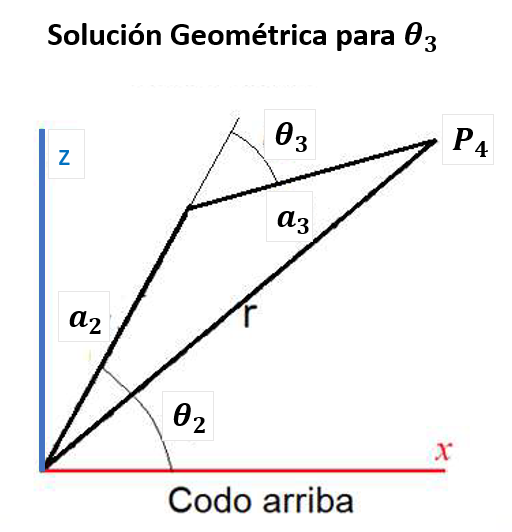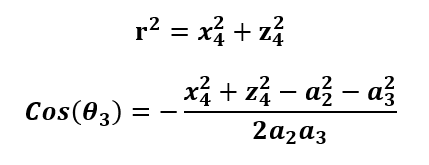

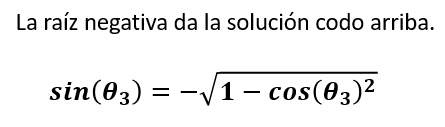

%Solución para q3:
a2=10.63 %cm

a2 = 10.6300

a3=10.5 %cm

a3 = 10.5000

cosq3=-(P04(1)^2+P04(3)^2-a2^2-a3^2)/(2*a2*a3);
sinq3=-sqrt(1-cosq3^2); 
q3=atan2(sinq3,cosq3) %rad

q3 = -1.0275

- **Solución para q2: **

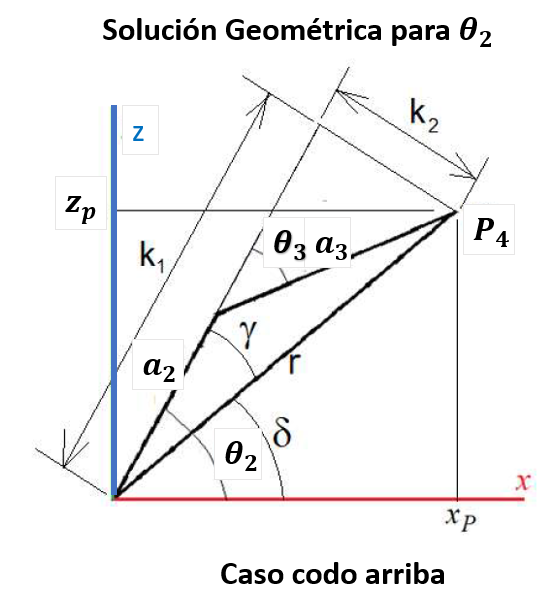

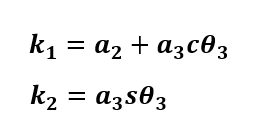

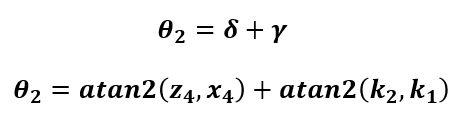

%Solución para q2: 
k1=a2+a3*cosq3

k1 = 16.0584

k2=a3*sinq3

k2 = -8.9879

q2=atan2(P04(3),P04(1))+atan2(k2,k1) %rad.

q2 = 1.3335

- **Solución para q4:**

Como q4 lo planteamos como la muñeca de un problema 2D en el plano XZ ,entonces su ecuación será: 


$$q_4 =\phi -q_2 -q_3$$


%Solución para q4: 
q4=phi-q2-q3 %rad.

q4 = -0.3061

**Solución: **

%Solución sin offsets.
Solg=[q1 q2 q3 q4] %rad

Solg =     0.7854    1.3335   -1.0275   -0.3061


%Solución con los offsets.
Solgof= [q1 q2+alpha2 q3-alpha2 q4] %rad

Solgof =     0.7854    2.5798   -2.2737   -0.3061


Solgd= Solg.*(180/pi) %grados.

Solgd =    45.0000   76.4063  -58.8697  -17.5366


**Comprobación por gráfica del Toolbox:**

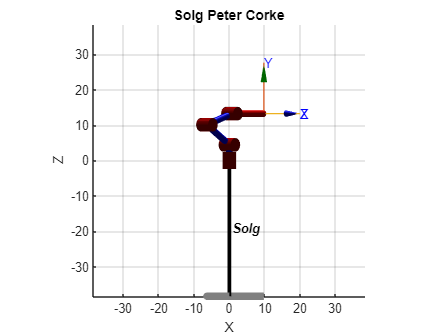

%configuracion Sol1=q1 q2 q3 q4 
robot1.name = 'Solg';
figure()
title('Solg Peter Corke')
Solgp=[Solg(1),Solg(2)+alpha2,Solg(3)-alpha2,Solg(4)];
robot1.plot(Solgp)
view([-22.3 7.9])
view([90 0])
view([0 0])

- **Comparación entre ambos métodos de solución: **

%Solucion por matrices inversas.
Sol1d %grados

Sol1d =    45.0000   57.4592  -36.2838  -51.7455


%Solucion geométrica:
Solgd %grados

Solgd =    45.0000   76.4063  -58.8697  -17.5366


function [H] = MTHDH(ai,alphai,di,thetai,angleType)
%Hecho por Andrés Felipe Forero Salas
%Función para calcular la Matriz de Transformación Homogénea
%dados los parámetros DHstd en diferentes posibles sistemas
%numéricos
%MTH para DH desde el marco i-1 al marco i.
    if angleType == 0 %rad
        H = [cos(thetai) -sin(thetai)*cos(alphai) sin(thetai)*sin(alphai) ai*cos(thetai);sin(thetai) cos(thetai)*cos(alphai) -cos(thetai)*sin(alphai) ai*sin(thetai); 0 sin(alphai) cos(alphai) di; 0 0 0 1];
    elseif angleType == 1 %degrees
        H = [cosd(thetai) -sind(thetai)*cosd(alphai) sind(thetai)*sind(alphai) ai*cosd(thetai);sind(thetai) cosd(thetai)*cosd(alphai) -cosd(thetai)*sind(alphai) ai*sind(thetai); 0 sind(alphai) cosd(alphai) di; 0 0 0 1];
    elseif angleType == 2 %alphai en degree,thetai en rad, 
        H = [cos(thetai) -sin(thetai)*cosd(alphai) sin(thetai)*sind(alphai) ai*cos(thetai);sin(thetai) cos(thetai)*cosd(alphai) -cos(thetai)*sind(alphai) ai*sin(thetai); 0 sind(alphai) cosd(alphai) di; 0 0 0 1];
    elseif angleType == 3 %alphai en rad,thetai en degree,
        H = [cosd(thetai) -sind(thetai)*cos(alphai) sind(thetai)*sin(alphai) ai*cosd(thetai);sind(thetai) cosd(thetai)*cos(alphai) -cosd(thetai)*sin(alphai) ai*sind(thetai); 0 sin(alphai) cos(alphai) di; 0 0 0 1];
    end
end

function [H] =MTHinv(MT)
%Sacar la inversa de una matriz de Transformación Homogenea.
R=MT(1:3,1:3);
D=MT(1:3,4);
R=R';
D=-R*D;
H=[R D ;0 0 0 1];
end